clear;
A_ = [1 1; 1 1]

A_ =      1     1
     1     1


B_ = [1; 1]

B_ =      1
     1



eig_a = eig(A_)

eig_a =      0
     2


eig_a(2)

ans = 2

jj = [A_-eig_a(2)*eye(2), B_]

jj =     -1     1     1
     1    -1     1


rank(jj)

ans = 2

U = [B_ A_*B_]

U =      1     2
     1     2


ru = rank(U)

ru = 1



syms s


k = 114.49;
T = 0.077;

kp = 5;

W = simplify(k * kp / (T * s^2 + s));
Y = simplify(W / (1 + W))

$$Y = \frac{572450}{77\,s^{2}+1000\,s+572450}$$

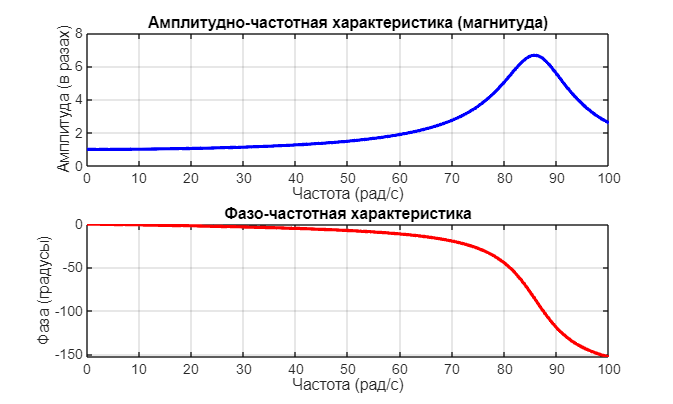

w = linspace(0, 100, 1000); % 1000 точек для хорошего разрешения
s = 1j * w; % Комплексная переменная s = jw

den_val = 77 * s.^2 + 1000 * s + 572450;

% Частотный отклик H(jw)
H = 572450 ./ den_val; % Комплексное значение

mag = abs(H);

% Фаза в радианах
phase_rad = angle(H);

% Преобразуем фазу в градусы (если нужно)
phase_deg = phase_rad * (180 / pi);

% График магнитуды
figure('Position', [100 100 1000 600]);
subplot(2, 1, 1)
plot(w, mag, 'b', 'LineWidth', 2);
grid on;
xlabel('Частота (рад/с)');
ylabel('Амплитуда (в разах)');
title('Амплитудно-частотная характеристика (магнитуда)');

% График фазы
subplot(2, 1, 2)
plot(w, phase_deg, 'r', 'LineWidth', 2);
grid on;
xlabel('Частота (рад/с)');
ylabel('Фаза (градусы)');
title('Фазо-частотная характеристика');

syms s

G = vpa(1 / (77 / 572450 * s^2 + 1000 / 572450 * s + 1), 10)

$$G = \frac{1}{0.0001345095642\,s^{2}+0.001746877457\,s+1.0}$$

T = sqrt(77 / 572450);
xi = 1000 / 572450 / T / 2

xi = 0.0753

ans = sqrt(1 - xi^2) / T

ans = 85.9782